# Matrix Completion of Union-of-subspaces data (dims=50x2000)

Demonstrates usage of vmc.m in large-scale setting

## Generate random UoS data

rng(1);  %fix random seed
n = 50;  %ambient dim
r = 5;   %subspace dim
k = 10;   %number of subspaces
p = 200; %points per subspace
m = 45;  %samples per column
Xtrue = [];
for i=1:k
    U = orth(randn(n,r));
    Xtrue = [Xtrue, U*randn(r,p)];
end
s = size(Xtrue,2);

% subsample data uniformly at random over each column
sampmask = false(n,s);
for j = 1:s
    tmp = randperm(n);
    randind = tmp(1:m);
    sampmask(randind,j) = true;
end
samples = Xtrue(sampmask);
Xinit = zeros(n,s);
Xinit(sampmask) = samples;
disp('job done')

job done


## Verify data is high-rank

r = rank(Xtrue,1e-6); %rank in original domain
R = rank((Xtrue'*Xtrue).^2,1e-6); %rank in lifted domain
N = nchoosek(n+1,2);
fprintf('original matrix: dim = %d-by-%d,\t rank=%d\n',n,s,r);

original matrix: dim = 50-by-2000,	 rank=50


fprintf('lifted matrix:   dim = %d-by-%d,\t rank=%d\n',N,s,R);

lifted matrix:   dim = 1275-by-2000,	 rank=150


disp('job done')

job done


## Run low-rank matrix completion (LRMC)

options_nn.lambda = 1e8;
options_nn.mu = 1;
options_nn.niter = 500;
Xlrmc = lrmc_admm(Xinit,sampmask,samples,options_nn);
fprintf('LRMC NRMSE = %1.2e\n',norm(Xlrmc-Xtrue,'fro')/norm(Xtrue,'fro'));

LRMC NRMSE = 1.72e-01


disp('job done')

job done


## Run variety-based matrix completion (VMC)

options = [];
options.d = 2; %kernel degree
options.eigcomp = 'kernel-rsvd';
options.rmax = 200; %maximum number of kernel eigenvalues to compute
%should be an overestimate of the expected rank
%in the lifted domain
options.eigtol = 1e-4; %threshold for adaptive rank cutoff
options.niter = 2000;
options.epsilon = 0;    %no noise
options.exit_tol = 1e-7;

%runtime ~6 minutes on Macbook Pro
tic;
[Xvmc,cost,update,error] = vmc(Xinit,sampmask,samples,options,Xtrue);

rsvd rank cutoff updated to r=200 at iter=397
rsvd rank cutoff updated to r=199 at iter=399
rsvd rank cutoff updated to r=198 at iter=401
rsvd rank cutoff updated to r=196 at iter=402
rsvd rank cutoff updated to r=194 at iter=404
rsvd rank cutoff updated to r=192 at iter=405
rsvd rank cutoff updated to r=191 at iter=406
rsvd rank cutoff updated to r=190 at iter=407
rsvd rank cutoff updated to r=188 at iter=408
rsvd rank cutoff updated to r=187 at iter=409
rsvd rank cutoff updated to r=186 at iter=410
rsvd rank cutoff updated to r=185 at iter=411
rsvd rank cutoff updated to r=184 at iter=412
rsvd rank cutoff updated to r=183 at iter=414
rsvd rank cutoff updated to r=181 at iter=415
rsvd rank cutoff updated to r=179 at iter=417
rsvd rank cutoff updated to r=177 at iter=419
rsvd rank cutoff updated to r=176 at iter=420
rsvd rank cutoff updated to r=175 at iter=422
rsvd rank cutoff updated to r=173 at iter=424
rsvd rank cutoff updated to r=172 at iter=426
rsvd rank cutoff updated to r=170 

toc;

Elapsed time is 225.066725 seconds.



fprintf('VMC NRMSE = %1.2e\n',norm(Xvmc-Xtrue,'fro')/norm(Xtrue,'fro'));

VMC NRMSE = 1.33e-05


## Display columnwise errors

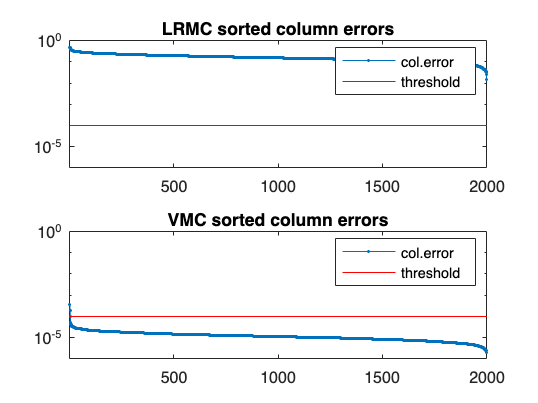

colerr_vmc = zeros(1,s);
colerr_lrmc = zeros(1,s);
for j = 1:s
    colerr_vmc(j) = norm(Xvmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
    colerr_lrmc(j) = norm(Xlrmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
end
[colerr_vmc,idx] = sort(colerr_vmc,'descend');
[colerr_lrmc,idx] = sort(colerr_lrmc,'descend');
errthresh = 1e-4;

figure(1);
subplot(2,1,1);
semilogy(colerr_lrmc,'.-'); title('LRMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
axis([1 s 1e-6 1]);
legend('col.error','threshold');
subplot(2,1,2);
semilogy(colerr_vmc,'.-'); title('VMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
legend('col.error','threshold');
axis([1 s 1e-6 1]);

fprintf('LRMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_lrmc < errthresh)/s)*100,nnz(colerr_lrmc < errthresh),s,errthresh);

LRMC recovered 0.0% columns (0 of 2000) with err < 1.0e-04


fprintf('VMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_vmc < errthresh)/s)*100,nnz(colerr_vmc < errthresh),s,errthresh);

VMC recovered 99.9% columns (1998 of 2000) with err < 1.0e-04


disp('job done')

job done
